clear;
clc;
syms x1 y1 theta1 x2 y2 theta2 L1 L2 t vx vy;

q = [x1;y1;theta1;x2;y2;theta2];

phi_c = [x1-sin(theta1)*L1/2; y1+cos(theta1)*L1/2;
         x1+sin(theta1)*L1/2-x2+sin(theta2)*L2/2; 
         y1-cos(theta1)*L1/2-y2-cos(theta2)*L2/2;];
phi_s = [x2+L2/2*sin(theta2)+L1-vx*t;     % or L1*sin(theta1)+L2*sin(theta2)+L-vx*t
         y2-L2/2*cos(theta2)+L2-vy*(t-1)*sin(pi*(t-1))];    % or L1*cos(theta1)+L2*cos(theta2)+L-vy*t
phi = [phi_c; phi_s];


syms m1 m2 mu1 mu2 g

mu1 = 1/12*m1*L1^2;
mu2 = 1/12*m2*L2^2;
m = [m1;m1;mu1;m2;m2;mu2];
M = diag(m);
g_k = [0;-m1*g;0;0;-m2*g;0];


phi_q = jacobian(phi,q);
phi_t = jacobian(phi,t);

phi_qt = diff(jacobian(phi,q),t);
phi_tt = diff(jacobian(phi,t),t);


syms x_dot_1 y_dot_1 theta_dot_1 x_dot_2 y_dot_2 theta_dot_2
q_dot_v = [x_dot_1;y_dot_1;theta_dot_1;x_dot_2;y_dot_2;theta_dot_2];
gamma = -((jacobian(phi_q*q_dot_v,q))*q_dot_v + 2*phi_qt*q_dot_v+phi_tt);

q_dot = -phi_q\phi_t;
q_dot_dot = phi_q\gamma;


syms lambda1 lambda2 lambda3 lambda4 T1 T2

lambda = [lambda1;lambda2;lambda3;lambda4];
g_u=[0;0;T1;0;0;T2];

F = (jacobian(phi_c,q)'*lambda+g_k+g_u-M*q_dot_dot)

L1=0.29; L2=0.36; m1=2.27; m2=1.53; mu1=1.48e-2 ; mu2=7.04e-3 ;g=10;
F = subs(F)

q_val=[];
q_dotval=[];
q_dotdotval=[];
lambda_val=[];

solution_q=[0;0;-pi/2;0;0;0];
solution_lambda=[0;0;0;0;0;0];



time=0:0.01:2;
j=1;
vx=0.29;
for t=time
    if t<=1
        vy=0;
    else
        vy=0.36;
    end
    Fq=subs(phi);
    fun1 = matlabFunction(Fq, 'Vars',{q})
    solution_q = fsolve(fun1,solution_q);
    q_val(:,j)=solution_q;
    
    q_dotval(:,j)=subs(subs(q_dot),[theta1;theta2],[q_val(3,j);q_val(6,j)]);
    
    q_dotdotval(:,j)=subs(subs(q_dot_dot),[theta1;theta2;theta_dot_1;theta_dot_2], ...
        [q_val(3,j);q_val(6,j);q_dotval(3,j);q_dotval(6,j)]);
    
    Fn = subs(subs(F),[theta1; theta2; theta_dot_1; theta_dot_2], ...
        [q_val(3,j);q_val(6,j);q_dotval(3,j);q_dotval(6,j)]);
    fun2 = matlabFunction(Fn, 'Vars',{[lambda;T1;T2]});
    solution_lambda = fsolve(fun2,solution_lambda);
    lambda_val(:,j) = solution_lambda; 
    j=j+1;
end

fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./1.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.871e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.842e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.813e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.74e+2./6.25e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.755e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.726e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.697e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.668e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.639e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.61e+2./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.581e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.552e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.523e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.494e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.465e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.436e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.407e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.378e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.349e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./1.25e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.291e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.262e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.233e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.204e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.7e+1./4.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.146e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.117e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.088e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.059e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.03e+2./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.001e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.972e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.943e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.914e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.885e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.16e+2./6.25e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.827e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.798e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.769e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.7e+1./5.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.711e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.682e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.653e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.624e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.595e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.566e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.537e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.508e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.479e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./2.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.421e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.7e+1./6.25e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.363e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.334e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.305e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.276e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.247e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.218e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.189e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./2.5e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.131e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.102e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.073e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.044e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.015e-1;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+9.86e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+9.57e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+5.8e+1./6.25e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.99e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.7e+1./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.41e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.12e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+7.83e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+7.54e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./4.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+6.96e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+6.67e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+6.38e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+6.09e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./5.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+5.51e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+5.22e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+4.93e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./6.25e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+4.35e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+4.06e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+3.77e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+3.48e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+3.19e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e+1./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.61e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.32e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.03e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.74e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.45e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+1.16e-2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+8.7e-3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+5.8e-3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)+2.9e-3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1);in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e-3;in1(5,:)-sin(pi./1.0e+2).*3.6e-3-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-5.8e-3;in1(5,:)-sin(pi./5.0e+1).*7.2e-3-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.7e-3;in1(5,:)-sin(pi.*(3.0./1.0e+2)).*1.08e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.16e-2;in1(5,:)-sin(pi./2.5e+1).*(9.0./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.45e-2;in1(5,:)-sin(pi./2.0e+1).*(9.0./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.74e-2;in1(5,:)-sin(pi.*(3.0./5.0e+1)).*2.16e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.03e-2;in1(5,:)-sin(pi.*(7.0./1.0e+2)).*2.52e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.32e-2;in1(5,:)-sin(pi.*(2.0./2.5e+1)).*(1.8e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.61e-2;in1(5,:)-sin(pi.*(9.0./1.0e+2)).*3.24e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(5.0).*(9.0./1.0e+3)+3.69e+2./1.0e+3]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-3.19e-2;in1(5,:)-sin(pi.*(1.1e+1./1.0e+2)).*3.96e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-3.48e-2;in1(5,:)-sin(pi.*(3.0./2.5e+1)).*(2.7e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-3.77e-2;in1(5,:)-sin(pi.*(1.3e+1./1.0e+2)).*4.68e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-4.06e-2;in1(5,:)-sin(pi.*(7.0./5.0e+1)).*5.04e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-4.35e-2;in1(5,:)-sin(pi.*(3.0./2.0e+1)).*(2.7e+1./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./6.25e+2;in1(5,:)-sin(pi.*(4.0./2.5e+1)).*(3.6e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-4.93e-2;in1(5,:)-sin(pi.*(1.7e+1./1.0e+2)).*6.12e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-5.22e-2;in1(5,:)-sin(pi.*(9.0./5.0e+1)).*6.48e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-5.51e-2;in1(5,:)-sin(pi.*(1.9e+1./1.0e+2)).*6.84e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./5.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(2.0).*sqrt(-sqrt(5.0)+5.0).*(9.0./5.0e+2)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-6.09e-2;in1(5,:)-sin(pi.*(2.1e+1./1.0e+2)).*7.56e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-6.38e-2;in1(5,:)-sin(pi.*(1.1e+1./5.0e+1)).*7.92e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-6.67e-2;in1(5,:)-sin(pi.*(2.3e+1./1.0e+2)).*8.28e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-6.96e-2;in1(5,:)-sin(pi.*(6.0./2.5e+1)).*(5.4e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./4.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(2.0).*(9.0./2.0e+2)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-7.54e-2;in1(5,:)-sin(pi.*(1.3e+1./5.0e+1)).*9.36e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-7.83e-2;in1(5,:)-sin(pi.*(2.7e+1./1.0e+2)).*9.72e-2-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.12e-2;in1(5,:)-sin(pi.*(7.0./2.5e+1)).*(6.3e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.41e-2;in1(5,:)-sin(pi.*(2.9e+1./1.0e+2)).*1.044e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.7e+1./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(5.0).*(2.7e+1./1.0e+3)+3.33e+2./1.0e+3]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.99e-2;in1(5,:)-sin(pi.*(3.1e+1./1.0e+2)).*1.116e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-5.8e+1./6.25e+2;in1(5,:)-sin(pi.*(8.0./2.5e+1)).*(7.2e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-9.57e-2;in1(5,:)-sin(pi.*(3.3e+1./1.0e+2)).*1.188e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-9.86e-2;in1(5,:)-sin(pi.*(1.7e+1./5.0e+1)).*1.224e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.015e-1;in1(5,:)-sin(pi.*(7.0./2.0e+1)).*(6.3e+1./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.044e-1;in1(5,:)-sin(pi.*(9.0./2.5e+1)).*(8.1e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.073e-1;in1(5,:)-sin(pi.*(3.7e+1./1.0e+2)).*1.332e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.102e-1;in1(5,:)-sin(pi.*(1.9e+1./5.0e+1)).*1.368e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.131e-1;in1(5,:)-sin(pi.*(3.9e+1./1.0e+2)).*1.404e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./2.5e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(2.0).*sqrt(sqrt(5.0)+5.0).*(9.0./2.5e+2)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.189e-1;in1(5,:)-sin(pi.*(4.1e+1./1.0e+2)).*1.476e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.218e-1;in1(5,:)-sin(pi.*(2.1e+1./5.0e+1)).*1.512e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.247e-1;in1(5,:)-sin(pi.*(4.3e+1./1.0e+2)).*1.548e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.276e-1;in1(5,:)-sin(pi.*(1.1e+1./2.5e+1)).*(9.9e+1./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.305e-1;in1(5,:)-sin(pi.*(9.0./2.0e+1)).*(8.1e+1./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.334e-1;in1(5,:)-sin(pi.*(2.3e+1./5.0e+1)).*1.656e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.363e-1;in1(5,:)-sin(pi.*(4.7e+1./1.0e+2)).*1.692e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.7e+1./6.25e+2;in1(5,:)-sin(pi.*(1.2e+1./2.5e+1)).*(1.08e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.421e-1;in1(5,:)-sin(pi.*(4.9e+1./1.0e+2)).*1.764e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./2.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./5.0e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.479e-1;in1(5,:)-sin(pi.*(4.9e+1./1.0e+2)).*1.836e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.508e-1;in1(5,:)-sin(pi.*(1.2e+1./2.5e+1)).*(1.17e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.537e-1;in1(5,:)-sin(pi.*(4.7e+1./1.0e+2)).*1.908e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.566e-1;in1(5,:)-sin(pi.*(2.3e+1./5.0e+1)).*1.944e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.595e-1;in1(5,:)-sin(pi.*(9.0./2.0e+1)).*(9.9e+1./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.624e-1;in1(5,:)-sin(pi.*(1.1e+1./2.5e+1)).*(1.26e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.653e-1;in1(5,:)-sin(pi.*(4.3e+1./1.0e+2)).*2.052e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.682e-1;in1(5,:)-sin(pi.*(2.1e+1./5.0e+1)).*2.088e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.711e-1;in1(5,:)-sin(pi.*(4.1e+1./1.0e+2)).*2.124e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.7e+1./5.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(2.0).*sqrt(sqrt(5.0)+5.0).*(2.7e+1./5.0e+2)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.769e-1;in1(5,:)-sin(pi.*(3.9e+1./1.0e+2)).*2.196e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.798e-1;in1(5,:)-sin(pi.*(1.9e+1./5.0e+1)).*2.232e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.827e-1;in1(5,:)-sin(pi.*(3.7e+1./1.0e+2)).*2.268e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.16e+2./6.25e+2;in1(5,:)-sin(pi.*(9.0./2.5e+1)).*(1.44e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.885e-1;in1(5,:)-sin(pi.*(7.0./2.0e+1)).*(1.17e+2./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.914e-1;in1(5,:)-sin(pi.*(1.7e+1./5.0e+1)).*2.376e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.943e-1;in1(5,:)-sin(pi.*(3.3e+1./1.0e+2)).*2.412e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.972e-1;in1(5,:)-sin(pi.*(8.0./2.5e+1)).*(1.53e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.001e-1;in1(5,:)-sin(pi.*(3.1e+1./1.0e+2)).*2.484e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.03e+2./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(5.0).*(6.3e+1./1.0e+3)+2.97e+2./1.0e+3]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.059e-1;in1(5,:)-sin(pi.*(2.9e+1./1.0e+2)).*2.556e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.088e-1;in1(5,:)-sin(pi.*(7.0./2.5e+1)).*(1.62e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.117e-1;in1(5,:)-sin(pi.*(2.7e+1./1.0e+2)).*2.628e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.146e-1;in1(5,:)-sin(pi.*(1.3e+1./5.0e+1)).*2.664e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-8.7e+1./4.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(2.0).*(2.7e+1./2.0e+2)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.204e-1;in1(5,:)-sin(pi.*(6.0./2.5e+1)).*(1.71e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.233e-1;in1(5,:)-sin(pi.*(2.3e+1./1.0e+2)).*2.772e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.262e-1;in1(5,:)-sin(pi.*(1.1e+1./5.0e+1)).*2.808e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.291e-1;in1(5,:)-sin(pi.*(2.1e+1./1.0e+2)).*2.844e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./1.25e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(2.0).*sqrt(-sqrt(5.0)+5.0).*(9.0./1.25e+2)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.349e-1;in1(5,:)-sin(pi.*(1.9e+1./1.0e+2)).*2.916e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.378e-1;in1(5,:)-sin(pi.*(9.0./5.0e+1)).*2.952e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.407e-1;in1(5,:)-sin(pi.*(1.7e+1./1.0e+2)).*2.988e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.436e-1;in1(5,:)-sin(pi.*(4.0./2.5e+1)).*(1.89e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.465e-1;in1(5,:)-sin(pi.*(3.0./2.0e+1)).*(1.53e+2./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.494e-1;in1(5,:)-sin(pi.*(7.0./5.0e+1)).*3.096e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.523e-1;in1(5,:)-sin(pi.*(1.3e+1./1.0e+2)).*3.132e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.552e-1;in1(5,:)-sin(pi.*(3.0./2.5e+1)).*(1.98e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.581e-1;in1(5,:)-sin(pi.*(1.1e+1./1.0e+2)).*3.204e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.61e+2./1.0e+3;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)-sqrt(5.0).*(8.1e+1./1.0e+3)+4.41e+2./1.0e+3]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.639e-1;in1(5,:)-sin(pi.*(9.0./1.0e+2)).*3.276e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.668e-1;in1(5,:)-sin(pi.*(2.0./2.5e+1)).*(2.07e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.697e-1;in1(5,:)-sin(pi.*(7.0./1.0e+2)).*3.348e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.726e-1;in1(5,:)-sin(pi.*(3.0./5.0e+1)).*3.384e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.755e-1;in1(5,:)-sin(pi./2.0e+1).*(1.71e+2./5.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-1.74e+2./6.25e+2;in1(5,:)-sin(pi./2.5e+1).*(2.16e+2./6.25e+2)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.813e-1;in1(5,:)-sin(pi.*(3.0./1.0e+2)).*3.492e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.842e-1;in1(5,:)-sin(pi./5.0e+1).*3.528e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.871e-1;in1(5,:)-sin(pi./1.0e+2).*3.564e-1-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


fun1 = function_handle with value:
    @(in1)[in1(1,:)-sin(in1(3,:)).*(2.9e+1./2.0e+2);in1(2,:)+cos(in1(3,:)).*(2.9e+1./2.0e+2);in1(1,:)-in1(4,:)+sin(in1(3,:)).*(2.9e+1./2.0e+2)+sin(in1(6,:)).*(9.0./5.0e+1);in1(2,:)-in1(5,:)-cos(in1(3,:)).*(2.9e+1./2.0e+2)-cos(in1(6,:)).*(9.0./5.0e+1);in1(4,:)+sin(in1(6,:)).*(9.0./5.0e+1)-2.9e+1./1.0e+2;in1(5,:)-cos(in1(6,:)).*(9.0./5.0e+1)+9.0./2.5e+1]



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


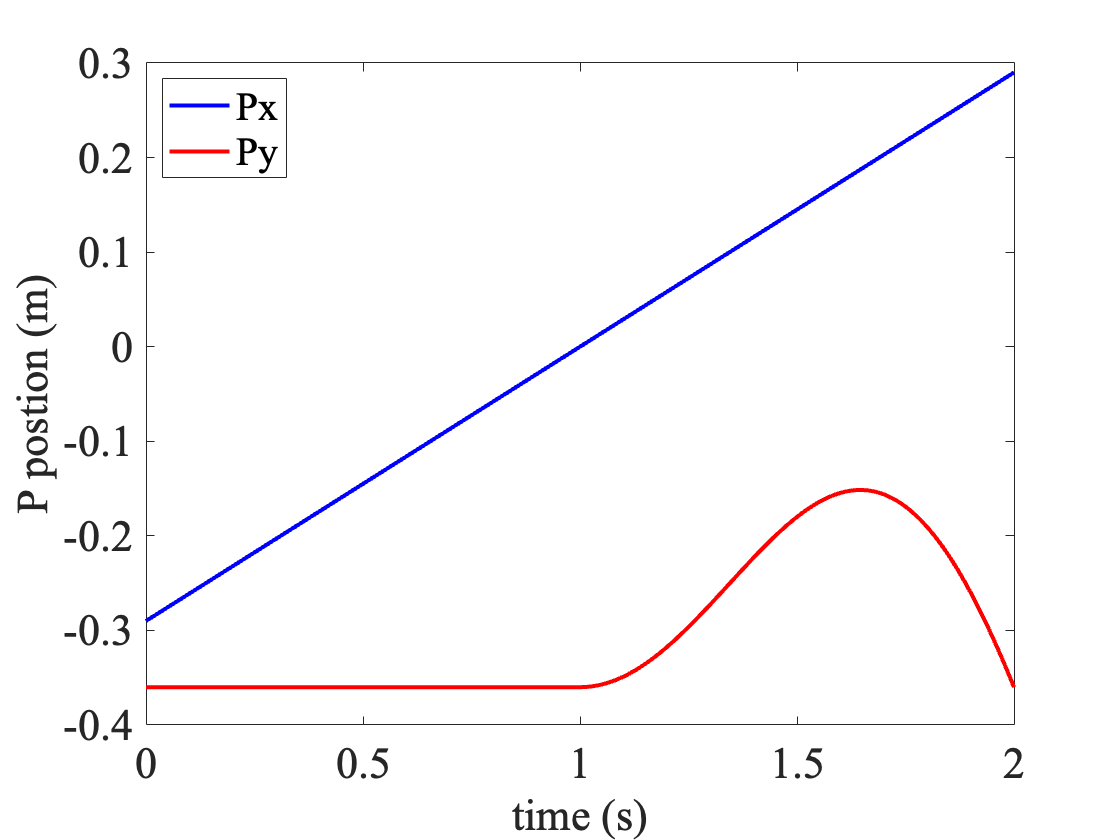

point_Px=q_val(4,:)+L2/2*sin(q_val(6,:));
point_Py=q_val(5,:)-L2/2*cos(q_val(6,:));


plot(time,point_Px,"LineWidth",2,"LineStyle","-","Color",'b')
hold on
plot(time,point_Py,"LineWidth",2,"LineStyle","-","Color",'r')
hold off
legend({'Px','Py'},"Location","northwest")
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('time (s)',"FontSize",22)
ylabel('P postion (m)',"FontSize",22)

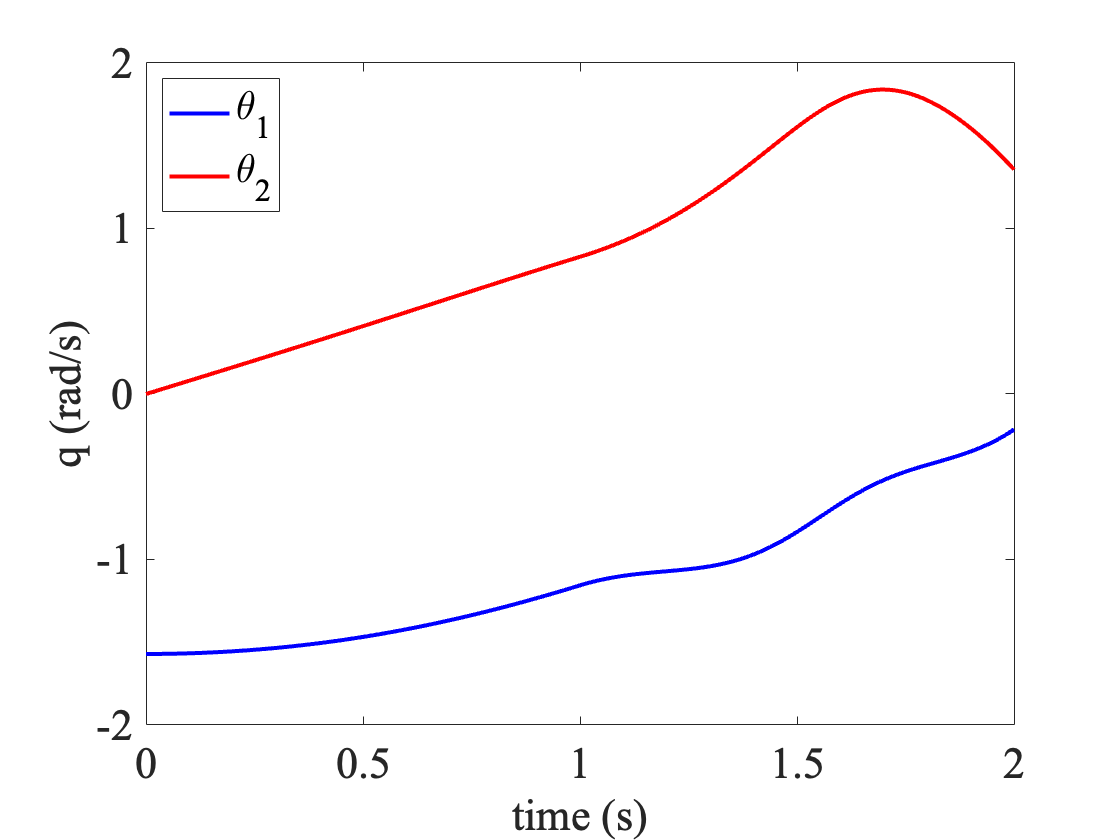

%print('-dpng','P_positon.jpg','-r1200')

plot(time,q_val(3,:),"LineWidth",2,"LineStyle","-","Color",'b')
hold on
plot(time,q_val(6,:),"LineWidth",2,"LineStyle","-","Color",'r')
hold off
legend({'\theta_1','\theta_2'},"Location","northwest")
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('time (s)',"FontSize",22)
ylabel('q (rad/s)',"FontSize",22)

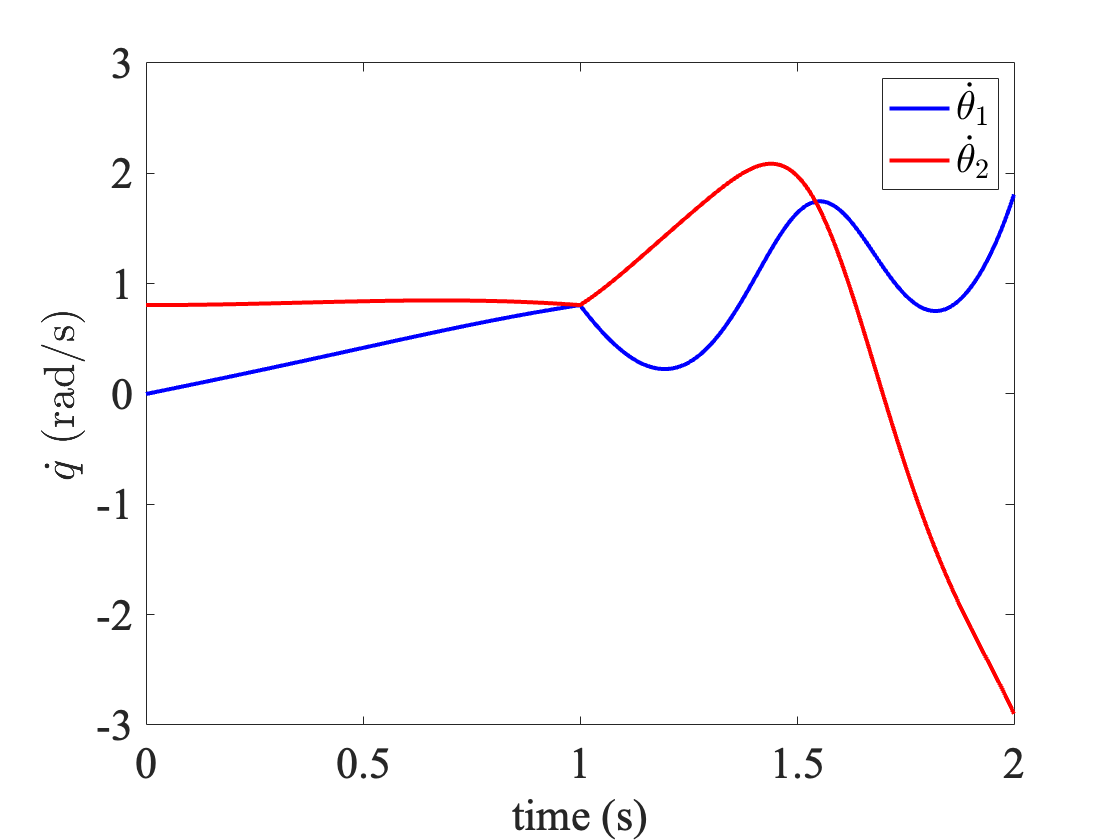

%print('-dpng','q.jpg','-r1200')

plot(time,q_dotval(3,:),"LineWidth",2,"LineStyle","-","Color",'b')
hold on
plot(time,q_dotval(6,:),"LineWidth",2,"LineStyle","-","Color",'r')
hold off
legend({'$\dot{\theta}_1$','$\dot{\theta}_2$'}, 'Interpreter','latex')
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('time (s)',"FontSize",22)
ylabel('$\dot{q}$ (rad/s)',"FontSize",22, 'Interpreter','latex')

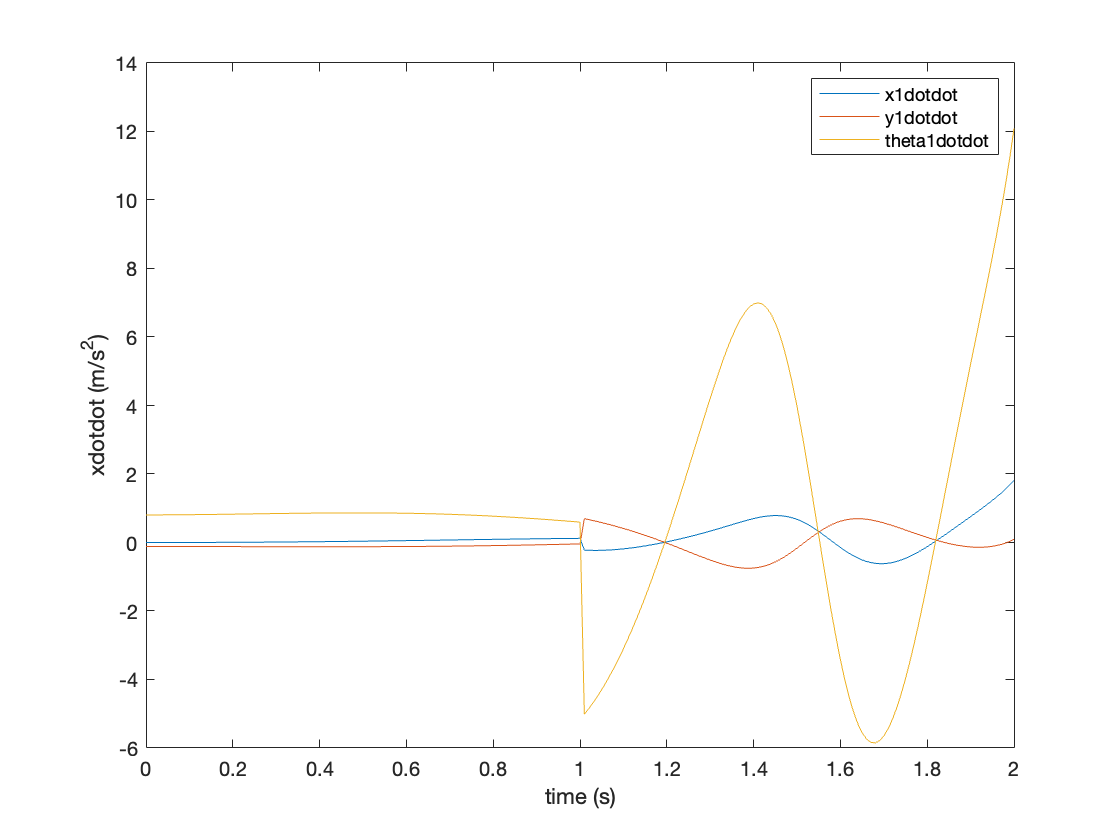

%print('-dpng','q_dot.jpg','-r1200')

plot(time,q_dotdotval(1,:))
hold on
plot(time,q_dotdotval(2,:))
plot(time,q_dotdotval(3,:))
hold off
legend({'x1dotdot','y1dotdot','theta1dotdot'})
xlabel('time (s)')
ylabel('xdotdot (m/s^2)')

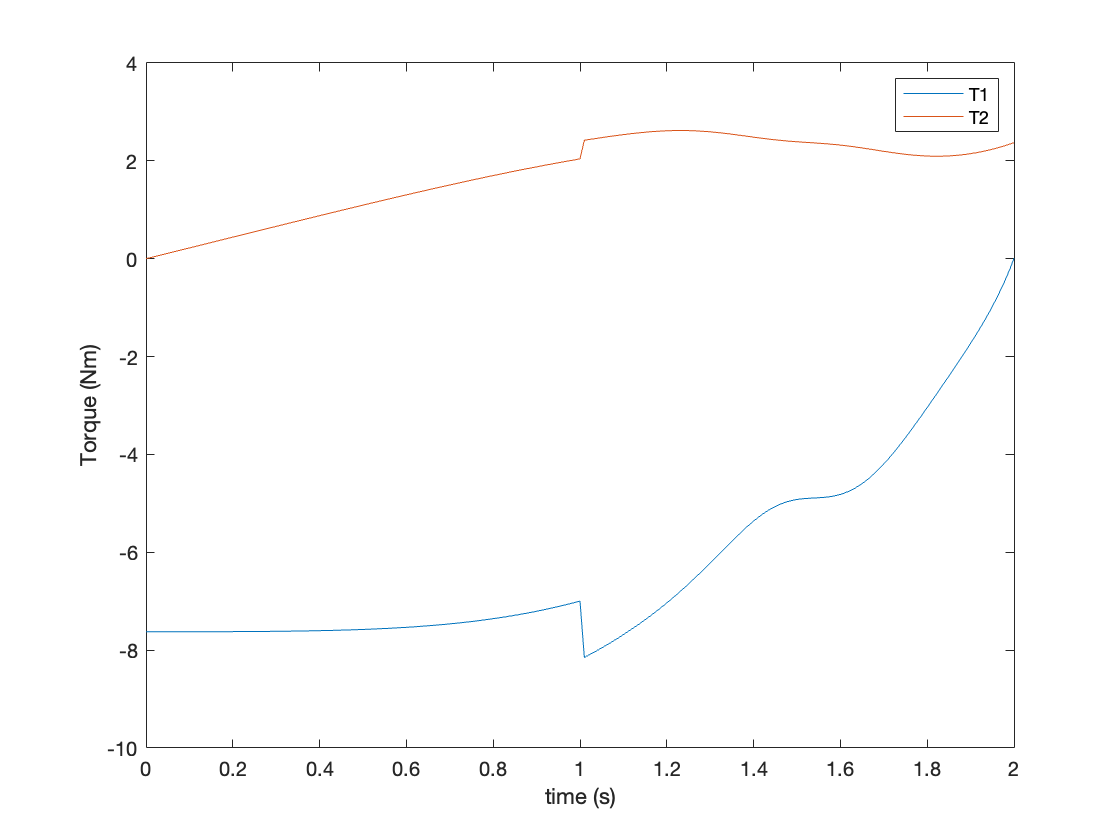


plot(time,lambda_val(5,:))
hold on
plot(time,lambda_val(6,:))
hold off
legend({'T1','T2'})
xlabel('time (s)')
ylabel('Torque (Nm)')


T1= [time',lambda_val(5,:)'+lambda_val(6,:)'];
T2= [time',lambda_val(6,:)'];

q1= [time',q_val(3,:)'];
q2= [time',q_val(6,:)'-q_val(3,:)'];

q1_dot= [time',q_dotval(3,:)'];
q2_dot= [time',q_dotval(6,:)'-q_dotval(3,:)'];

q1_dotdot= [time',q_dotdotval(3,:)'];
q2_dotdot= [time',q_dotdotval(6,:)'-q_dotdotval(3,:)'];


%k1=1;k2=1;c1=1;c2=1;
%p1=1;p2=1;i1=1;i2=1;d1=1;d2=1;

%c1=39.0666;c2=32.889;k1=718.280;k2=95.812; %data driven controller
%d1=29.181;d2=6.927;i1=40.179;i2=20.596;p1=86.636;p2=46.006; %pid controller
%d1=38.916;d2=28.688;p1=180.700;p2=74.835; %pd controller

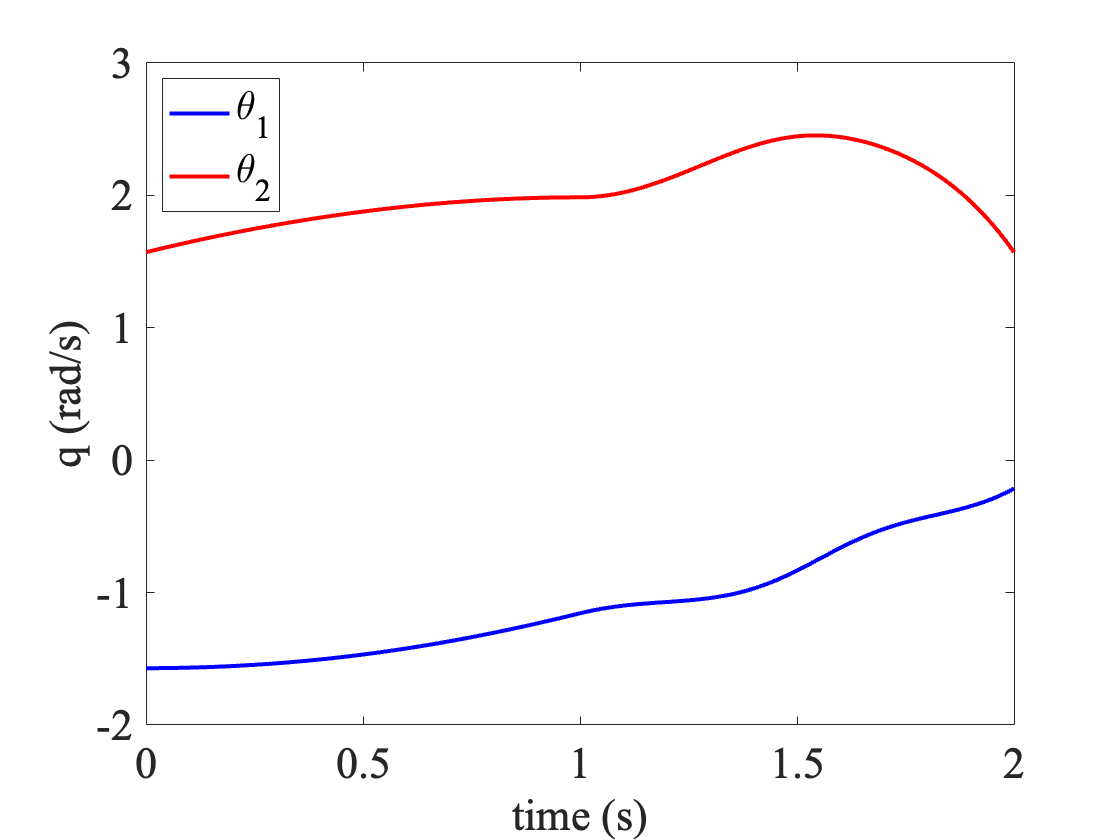

plot(time,q_val(3,:),"LineWidth",2,"LineStyle","-","Color",'b')
hold on
plot(time,q_val(6,:)-q_val(3,:),"LineWidth",2,"LineStyle","-","Color",'r')
hold off
legend({'\theta_1','\theta_2'},"Location","northwest")
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('time (s)',"FontSize",22)
ylabel('q (rad/s)',"FontSize",22)

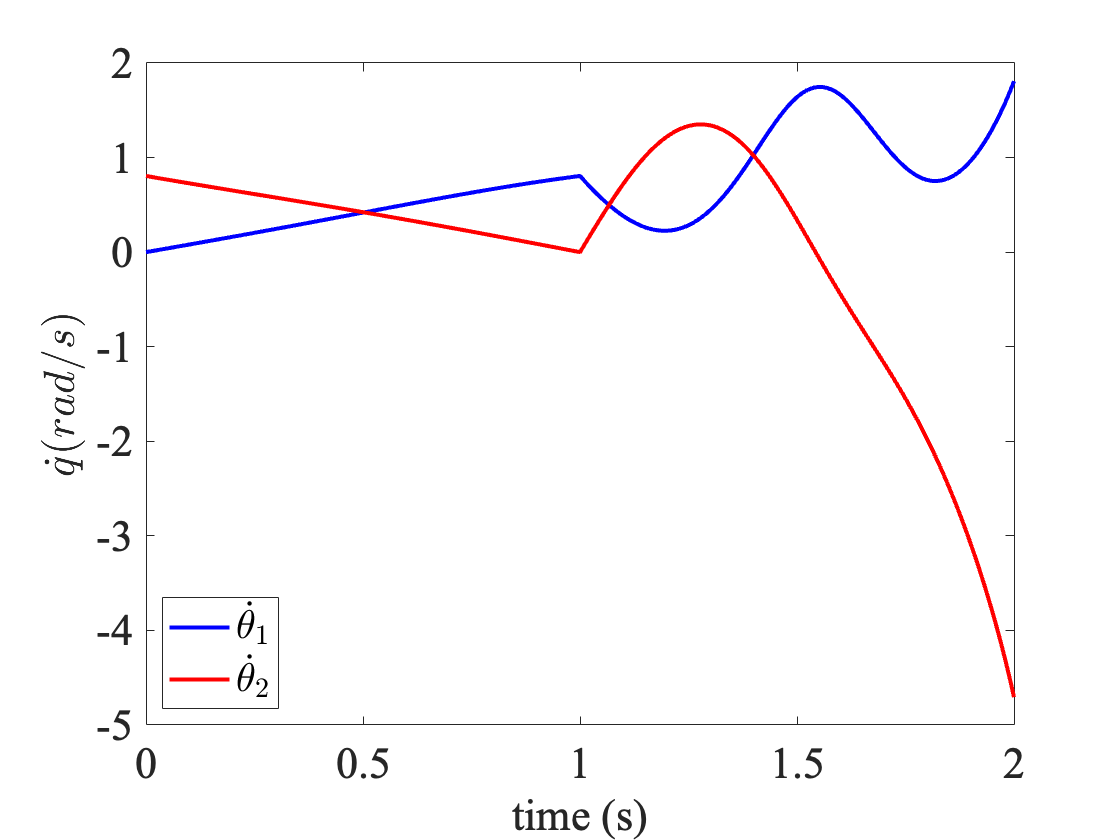

%print('-dpng','q.jpg','-r1200')

plot(time,q_dotval(3,:),"LineWidth",2,"LineStyle","-","Color",'b')
hold on
plot(time,q_dotval(6,:)-q_dotval(3,:),"LineWidth",2,"LineStyle","-","Color",'r')
hold off
legend({'$\dot{\theta}_1$','$\dot{\theta}_2$'}, 'Interpreter','latex',"Location","southwest")
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('time (s)',"FontSize",22)
ylabel('$\dot{q} (rad/s)$',"FontSize",22, 'Interpreter','latex')

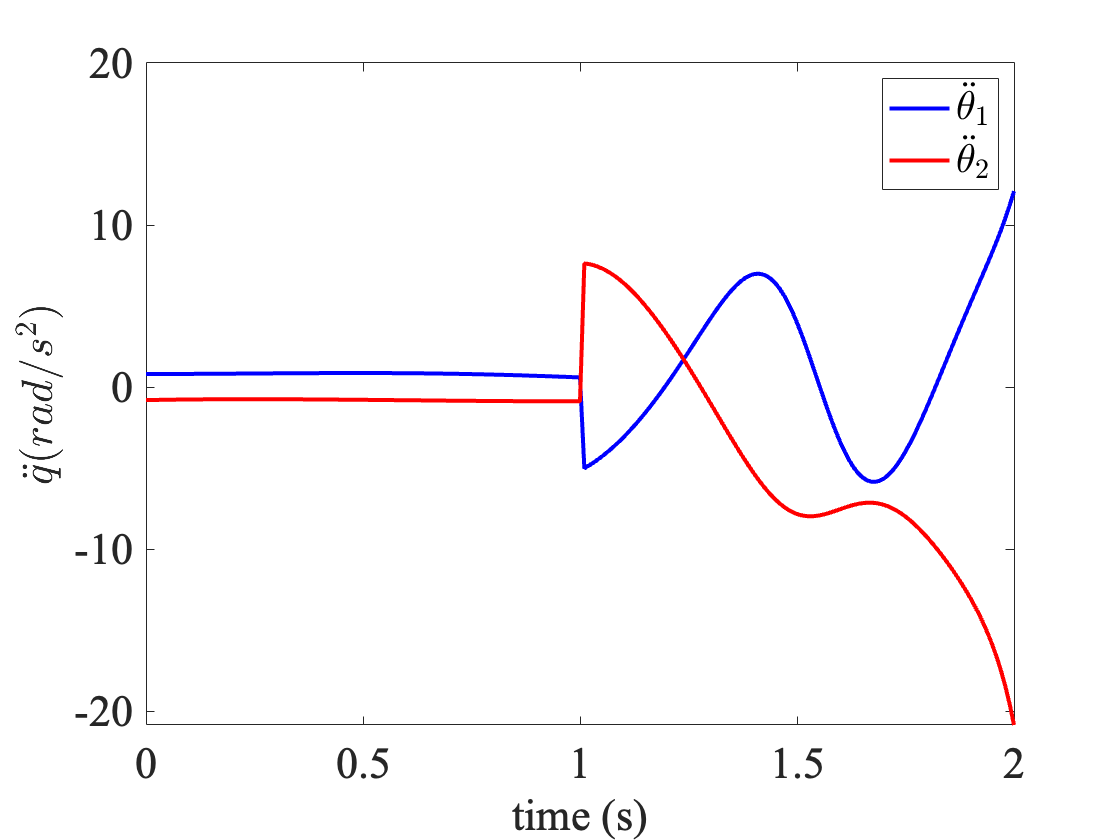

%print('-dpng','q_dot.jpg','-r1200')

plot(time,q_dotdotval(3,:),"LineWidth",2,"LineStyle","-","Color",'b')
hold on
plot(time,q_dotdotval(6,:)-q_dotdotval(3,:),"LineWidth",2,"LineStyle","-","Color",'r')
hold off
legend({'$\ddot{\theta}_1$','$\ddot{\theta}_2$'}, 'Interpreter','latex')
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('time (s)',"FontSize",22)
ylabel('$\ddot{q} (rad/s^2)$',"FontSize",22, 'Interpreter','latex')

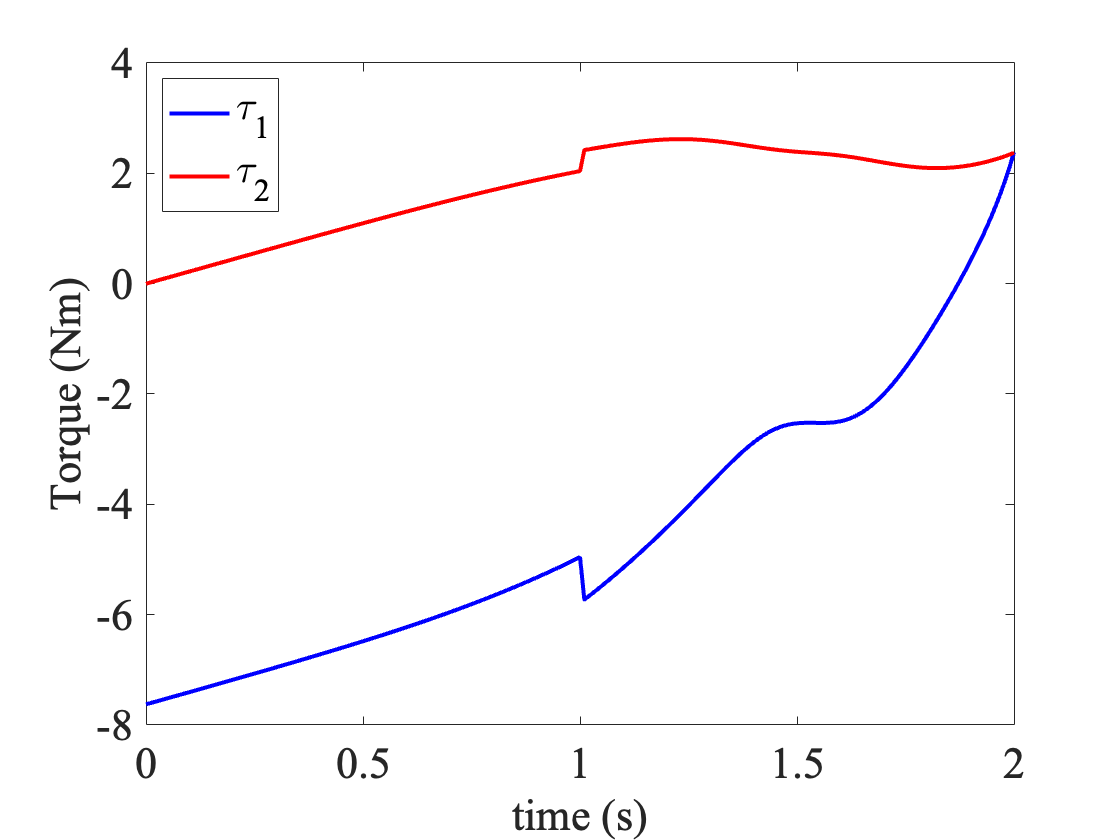

%print('-dpng','q_dotdot.jpg','-r1200')

plot(time,lambda_val(5,:)'+lambda_val(6,:)',"LineWidth",2,"LineStyle","-","Color",'b')
hold on
plot(time',lambda_val(6,:)',"LineWidth",2,"LineStyle","-","Color",'r')
hold off
legend({'\tau_1','\tau_2'},"Location","northwest")
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',22)
xticklabels("auto")
xlabel('time (s)',"FontSize",22)
ylabel('Torque (Nm)',"FontSize",22)

%print('-dpng','Torque.jpg','-r1200')

%csvwrite('time.csv',i.');
%csvwrite('T1.csv',lambda_val(5,:).');
%csvwrite('T2.csv',lambda_val(6,:).');
